选取并计算[-10,10]天内，发生分红派息事件后指数的平均收益率

l=600000;
ERMt=[];
while l<=603999
    [dividend_day,col]=find(dividendDay==l);
    dividend_day=dividendDay(dividend_day,2);
    position_matrix=[];
    i=1;
    while i<=numel(dividend_day)
        position_matrix=[position_matrix;find(RMt==dividend_day(i,1))];
        i=i+1;
    end
    %提取发生该事件[-10,10]天的数据
    revenue_matrix=[];
    i=1;
    while i<=numel(position_matrix)
        w=position_matrix(i,1);
        if w+10>numel(RMt)/2
            break
        end
        if w-10<1
            break 
        end
        revenue_matrix=[revenue_matrix;RMt(w-10:w+10,2)'];
        i=i+1;
    end
    if isempty(final_matrix)==0
        ERMt=[ERMt;revenue_matrix];      
    end
    l=l+1;
end
average_ERMt=[];
i=1;
while i<=21
    average_ERMt=[average_ERMt sum(ERMt(:,i))/2871];
    i=i+1;
end
average_ERMt=(average_ERMt/100)

average_ERMt =    -0.0020   -0.0017    0.0005   -0.0013   -0.0010   -0.0001   -0.0006    0.0009   -0.0008   -0.0030   -0.0023   -0.0013    0.0013   -0.0018   -0.0017   -0.0021    0.0001    0.0004   -0.0013    0.0002   -0.0011


ERit=(b.*average_ERMt)'%E(Ri,t)

ERit = 	1.0e+-4 *

   -0.0051   -0.0861
   -0.0043   -0.0727
    0.0012    0.0207
   -0.0034   -0.0572
   -0.0025   -0.0426
   -0.0002   -0.0026
   -0.0015   -0.0258
    0.0024    0.0399
   -0.0020   -0.0342
   -0.0077   -0.1312


ARit=average_Rit-average_ERMt

ARit =     1.0015    1.0012    1.0006    1.0013    1.0011    1.0015    1.0025    1.0002    1.0022    1.0027    0.9999    1.0006    1.0001    1.0024    1.0017    1.0019    1.0008    1.0002    1.0009    1.0006    1.0014


x=-10:10

x =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


y=ARit

y =     1.0015    1.0012    1.0006    1.0013    1.0011    1.0015    1.0025    1.0002    1.0022    1.0027    0.9999    1.0006    1.0001    1.0024    1.0017    1.0019    1.0008    1.0002    1.0009    1.0006    1.0014


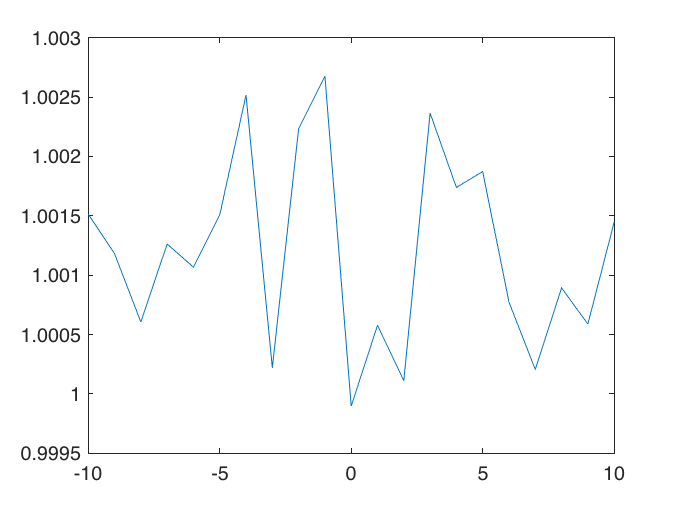

plot(x,y)